# Power, efficiency, colinearity, and variance inflation

### Dependencies and setup

This walkthrough uses [CANlab object-oriented analysis functions](http://canlab.github.io) with SPM12 basic functions  (e.g., image reading/writing, HRF) in Matlab.  

Do you have the relevant tools on your Matlab path?  

which create_design_single_event

If you get an error, you don't!  You need the [Canlab Core](https://canlab.github.io/repositories/) repository. See [this page](https://canlab.github.io/setup/) for setup instructions.

You also need the Statistics and Machine Learning Toolbox in Matlab. Try this to check:

if isempty(ver('stats')), warning('You do not have the statistics toolbox on your Matlab path. You may/will get errors'); end

### Experimental design

In previous labs, we constructed a single-subject fMRI design for multiple regressors (e.g., responses to famous faces upright and inverted), in a sparse event-related design.

We constructed a model (*X*), which is the predicted fMRI signal in a brain area that responds to faces, and fit it to the data. Fitting the model involves solving the equation $y=X{\hat{\beta}}$, where $y$ is a brain time series (a vector), $X$is the model or "design matrix", and $\hat{\beta}$ is the unknown vector of regression slopes or "parameters". ${\hat}$ or "hat" means something that is estimated from the data during model fitting. This model is fit to a single brain time series from a single person - for example, the average signal in a person's pre-identified "fusiform face area". 

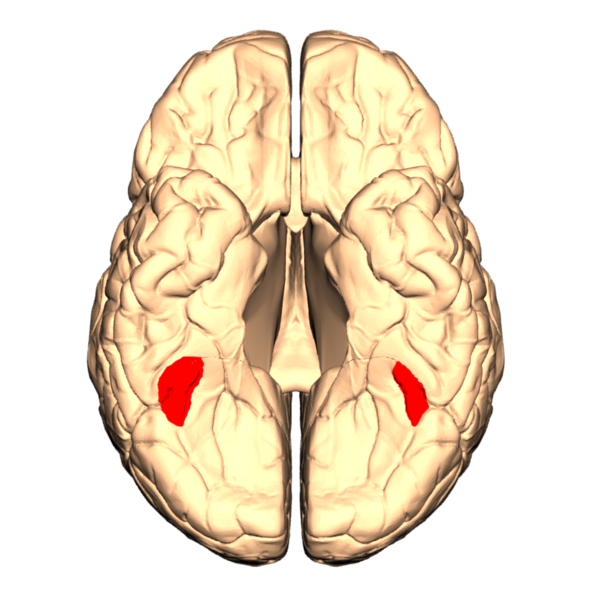

### Create a simple, one-event design

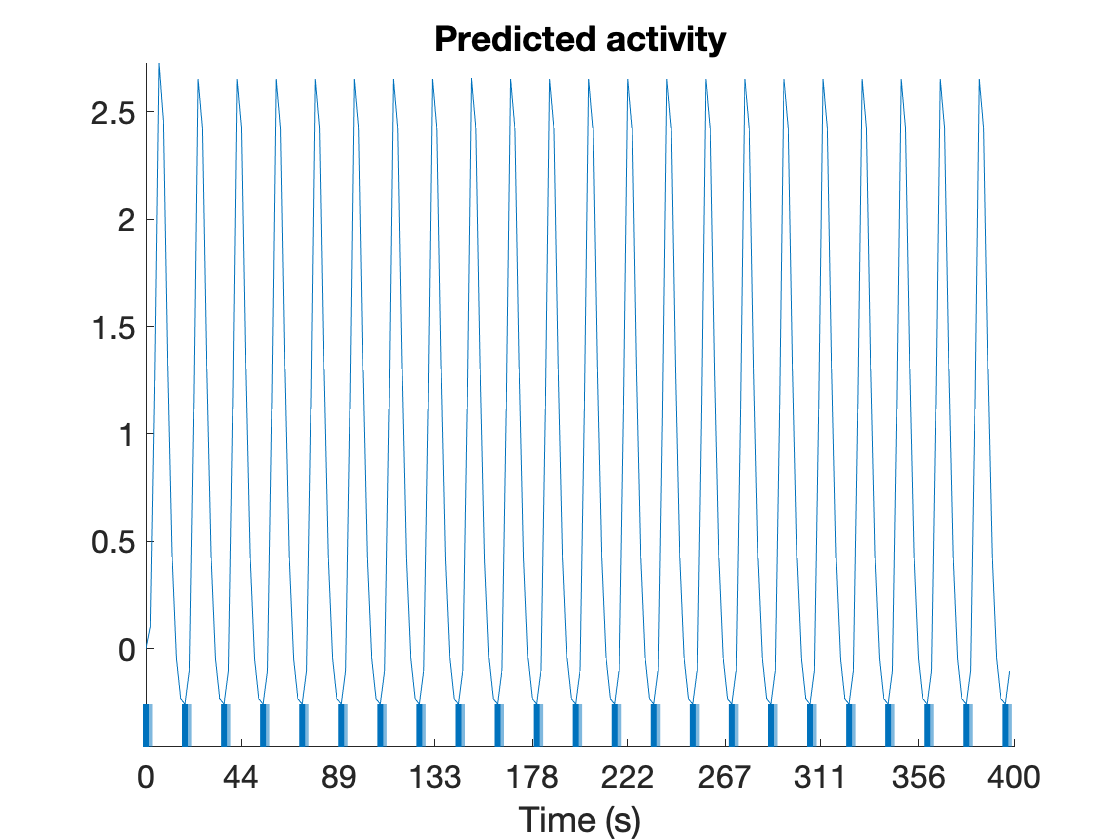

TR = 2;                 % Repetition time for scans; one image every TR; in seconds
ISI = 18;               % Inter-stimulus interval in sec (min time between events)
eventduration = 3;      % Duration of 'neural' events in sec
HPlength = 128;         % High-pass filter length in sec
dononlin = 0;           % Nonlinear saturation model (0 = no, 1 = yes)

create_figure('design');
[X, e] = create_design_single_event(TR, ISI, eventduration, HPlength, dononlin);

drawnow, snapnow


### *True and false positives, effect size, and power*

An important consideration for any fMRI design is its power. Statistical** power** is the ability to detect a true response should one exist (i.e., obtain a significant $\hat\beta$ for any given regressor). Power is defined as the "hit rate" for a statistical test, or the probability of finding a significant result. 

Power depends on the true **effect size** present in the data, and also on the **acceptable false positive rate**. In addition, different statistical tests can be more or less powerful at detecting the same true effect. Also, different fMRI designs can be more or less powerful depending on how the stimuli are arranged, which affects how they interact with the hemodynamic response (HRF) and scanner noise. 

We'll go over a (very!) brief primer on some basic concepts. First, we have to set an acceptable false positive rate, the chances of calling an effect significant in the absence of one (Ho is true). If you never want to detect a false positive, you shouldn't call anything significant ever, no matter how strong the evidence! But in practice, we want to balance false positives against the ability to find effects. The convention is to set the acceptable false positive rate to a fixed value, denoted $\alpha$. This is where p < 0.05 comes from -- alpha is 0.05.  Power is complementary, and it's denoted $1-\beta$ (not to be confused with regression slope betas - sorry!), for reasons we'll see below.

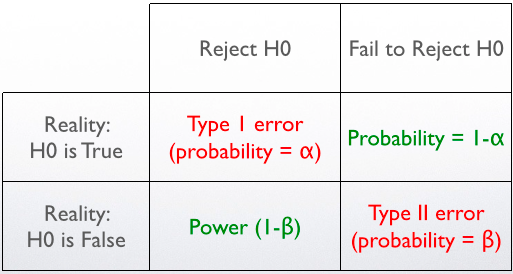

Another way to view this is by thinking of two possible universes, one in which Ho is true, and the other in which Ho is false (H1 is true below). Given each of these two universes, the observed effect magnitude will vary because the data are noisy, and we can assume this variability follows a normal distribution. Therefore, these two universes are described by two Normal curves, as shown below. The decision point to reject the null hypothesis is shown as a location on the x-axis, which indexes effect magnitude.  $\alpha$ is the proportion of cases where Ho is true but the effect magnitude is above threshold to reject, or "false alarms"/"false positives". This proportion is the area under the Ho curve, where all probability values sum to 1. They sum to 1 because in the universe where Ho is true, the probability that the effect falls between -infinity and +infinity is 1.  $\beta$ is the proportion of cases where Ho is false (H1 is true) and we fail to reject ("misses"). $1-\beta$ is the area under the curve where H1 is true and we correctly reject the null, which is the power. 

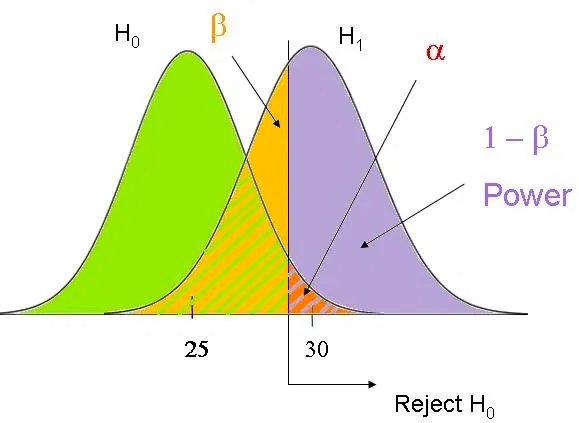

Where is the effect size here?  It's the distance between the peaks for H0 and H1. This reflects how much signal is there to detect, regardless of the statistical threshold for rejecting H0. 

Effect sizes are measures of signal to noise ratio, i.e., effect magnitude / effect standard error. Thus, the larger the true signal *relative to the noise*, the higher the power.   

To give us an intuition about power, we'll run a simulation. We'll generate 5,000 different datasets, with the same true effect but different random noise. The true effect magnitude will depend on the desired effect size. We'll standardize (z-score) the first column of X, the "true" signal (our "faces" regressor), and multiply it by the desired effect size. Then, we'll add noise, with a standard deviation fixed at 1 is fixed at 1, because y = X(:, 1) [] + noise in the code below. (Note that because we're generating autocorrelated noise, the observed standard deviation will be a bit larger due to the autocorrelation.)

You can set the effect size with the slider.  Every time you adjust the slider, the simulation will run again. The **observed power** is calculated as the percentage of samples in which we obtain a significant result. 

% Set the noise level (formally, noise standard deviation) here:
% -------------------------------------------------------
effect_size =0.5

effect_size = 0.5000


n_iterations = 5000;        % Run this many iterations in our simulation

pval = Inf .* ones(n_iterations, 1); % Initalize P-value array for all sims

true_signal = effect_size .* zscore(X(:, 1));  % do this to standardize the effect magnitude

for i = 1:n_iterations
    
    % Observed effect in sample
    % -------------------------------------------------------
    noise_ac = noise_arp(size(X, 1), [.7 .3]); % autocorrelated noise

    y = true_signal + noise_ac;                    % simulated data
    
    % Model fit
    % -------------------------------------------------------
    [b dev stats] = glmfit(X(:, 1), y);
    
    pval(i, 1) = stats.p(2);
end

is_sig = pval < 0.05; % which are significant

detection_power = sum(is_sig) ./ length(is_sig);

fprintf('Power is %3.1f%%\n', 100 .* detection_power)

Power is 43.6%


### Questions to answer

Now let's do an exercise that will require a bit of coding. You can start with the code above, and add an outer loop that saves an estimate of power for a series of different true effect sizes. We'll operationalize effect size here as . Then, you'll make a graph of power vs. effect size. 

This will start to introduce you to writing bits of code on your own. Try it on your own, and then check out the example code. If you get stuck, you can use bits of the example code, too -- but I made the font small so you can try it on your own first.

Before you start: What would you predict about the relationship between power and effect size? Will it be linear or nonlinear? What will the power be when the effect size is zero?

- Describe the relationship between effect size and power

- What is the "power" when the effect size is zero? If there is no true effect, the chances of finding an effect should be the **alpha level** -- the acceptable false positive rate level. This is the P-value cutoff we chose (0.05). Why might it be higher? How could you verify (or explore) why it might be higher?

- Re-run the simulation, but replace the autocorrelated noise with Gaussian (normally distributed, not autocorrelated) noise. The code below will help. What do you notice now about the power when the effect size is zero?

### *Design efficiency*

*e* is the "efficiency", a relative metric of how good the design is compared with others with the same number of time points. We can use efficiency to explore which choices make a "better" design and which create problems. We'll explore this a bit here. 

We won't go into a lot of detail here, but *e* is proportional to power. Efficiency, and therefore power, vary across designs as different choices are made -- e.g., do you scan for longer or shorter? How many event types (or conditions) are included? How much space is there between events? 

Efficiency (e) the reciprocal of the design-related component of the standard error.  Previously, we saw that $var(\hat\beta)$is a measure of error variance, and it's square root is the** standard error** of the estimate, which is the denominator of the *t* statistic. So higher $var(\hat\beta)$means less power.  

To estimate $var(\hat\beta)$, we need to know how noisy the data is. The noise (or error) variance is usually denoted with $\sigma$, so $\hat\sigma$ is the estimated noise variance. Specifically, $var(\hat\beta_i)=\hat\sigma^2(X^TX)_{ii}^{-1}$, where *i* denotes the ith column of X (i.e., regressor), and *ii* denotes the ith diagonal of the matrix resulting from the multiplication $(X^TX)^{-1}$. -1 here is the **inverse** operator. 

But here, we don't have any data yet! So while we can't calculate $var(\hat\beta)$, we can notice that part of the equation depends **purely on the design matrix** (X). So efficiency can be higher or lower independent of what the measurement error/noise level is. Efficiency is thus defined as $eff(\hat\beta)=1/trace{(X^TX)^{-1}}$, where the **trace** is the sum of diagonal elements. 

For a more detailed explanation and general experimental design recommendations see this [overview](http://imaging.mrc-cbu.cam.ac.uk/imaging/DesignEfficiency) by Rik Henson, or this [blog post](https://theclevermachine.wordpress.com/tag/fmri-design-efficiency/) on efficiency in experimental designs.

Let's explore this using our simple, one-event design:

#### Create a simple, one-event design

TR = 2;                 % Repetition time for scans; one image every TR; in seconds
ISI = 18;               % Inter-stimulus interval in sec (min time between events)
eventduration = 3;      % Duration of 'neural' events in sec
HPlength = 128;         % High-pass filter length in sec
dononlin = 0;           % Nonlinear saturation model (0 = no, 1 = yes)

create_figure('design');
[X, e] = create_design_single_event(TR, ISI, eventduration, HPlength, dononlin);
drawnow, snapnow


fprintf('Efficiency: %3.2f\n', e)

Efficiency is e. More is better. Explore efficiency here by changing some of the parameters.

#### Questions to answer

1. Make the events really brief (0.5 sec). What happens to the efficiency?

2. Make the events really long (17 sec). What happens to the efficiency?

3. What are some other ways you might be able to increase the efficiency of the design?

5. Explore different event durations systematically by running the code below. Make a plot of the curve showing efficiency from 1 to 18 sec event duration. Where is efficiency maximal? Why does this make sense?

Block designs

Now, let's create a block design.  

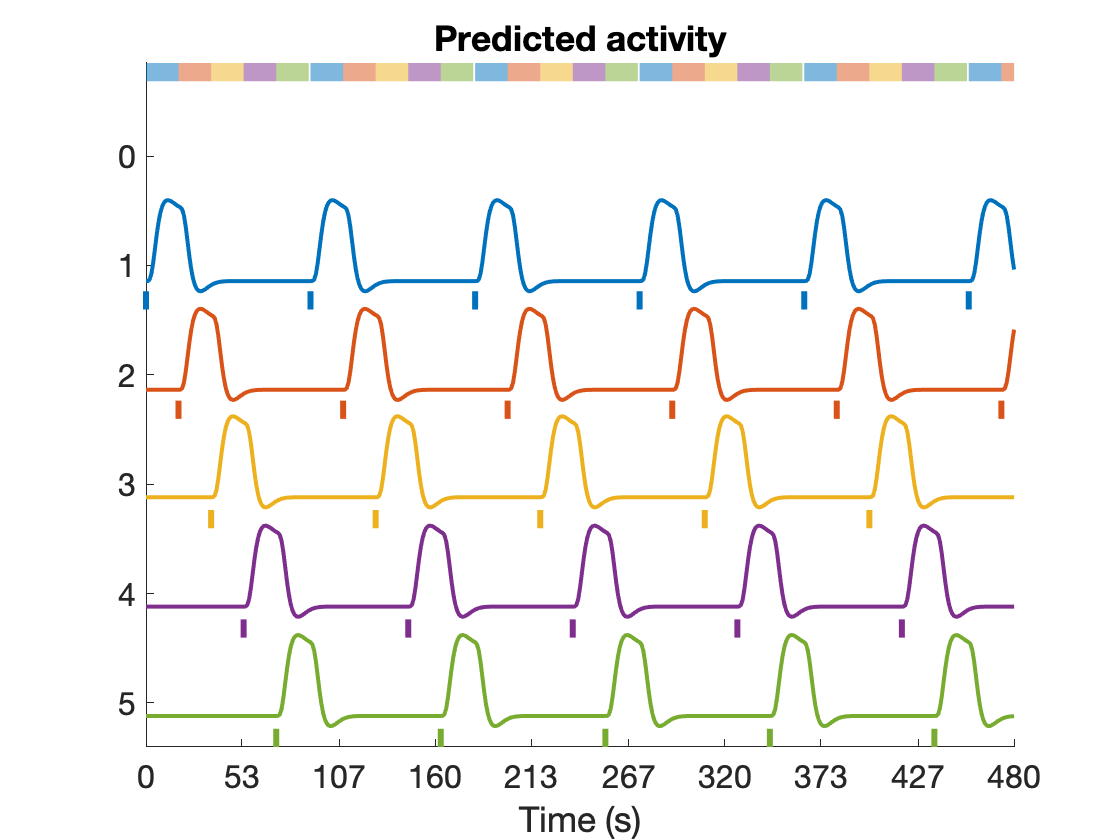

scanLength = 480;
nconditions = 5;
blockduration = 18;

create_figure('block design');
[X, e] = create_block_design(scanLength, TR, nconditions, blockduration, HPlength, dononlin);


fprintf('Efficiency: %3.2f\n', e)

Efficiency: 1414.72


#### Questions to answer

1. What do you notice about the efficiency of the block vs. event-related design?

2. To make things fair, you have to equate the scan time (length). If you do this, is the block design still more efficient?

3. What happens to efficiency as you increase the number of conditions?

**A caveat: **Efficiency is not a perfect guide to which designs are best, as it is based on a linear time-invariant system, i.e., responses to different events can sum up without bound, whereas activity in the real brain will not be able to keep increasing without bound. So it's possible to create designs that look good efficiency-wise because they create very high-amplitude predicted signals in an unrealistic fashion -- e.g., by summing responses across densely packed events, or across very long, overlapping events. In addition, the effects of increasing event duration are going to have unrealistically large benefits on efficiency, as convolution is going to turn these into high predicted-amplitude signals that will increase efficiency much more than the power would increase in a real experiment.  The parameter dononlin attempts to adjust for this, but it also is very approximate for complex reasons we won't go into here.

### Colinearity

If designs are efficient, the parameters can be estimated precisely (with low error), and power increases. Efficiency is a function of three features of the design:

- More data (longer scan length)

- Higher predictor variance (rise and fall of predicted signal)

- Minimal **multicolinearity**, and ideally orthogonality.

**Multicolinearity** refers to how related regressors are to one another.  As regressors become more highly correlated, they make similar predictions about the data. If they are perfectly correlated (r = 1), they make identical predictions, and the linear model cannot assign credit among them. They are "colinear" because they fall on the same line in geometric space, and the angle between them is 0. The equation ${\hat{\beta}}=(X^TX)^{-1}X^Ty$ becomes unsolvable because there is no unique solution. 

If colinearity is high, parameter estimates become unstable: Their variances increase.  In addition, the parameter estimates themselves become correlated. If regressors are positively correlated, their parameter estimates will be negatively correlated, and vice versa.

Alternatively, a perfect situation is one in which the regressors are **orthogonal**, meaning at right angles. In this case, the regressors will be uncorrelated (r = 0), and so are their parameter estimates. Each $\hat\beta$ is estimated with maximum precision, and power is also maximized.

#### Simulate a design with multicolinearity

We'll create a random event-related design. The CANlab function **create_random_er_design** gives us lots of flexibility to create designs with different parameters and options.  

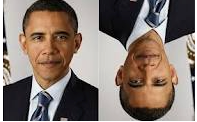

In the code below, one event will be presented each *ISI* sec, for *eventduration* sec.

The variable *freqConditions* controls how many conditions there are, and what their relative frequencies are. They are entered in proportions (0 to 1) and will often sum to 1 (for 100% of the trials). If they don't, the remainder (0.2 in this case, as 0.4 + 0.4 sums to 0.8) will be assigned to **rest** - that is, no event type. This effectively randomizes the time between event presentations (in units of *ISI* sec, or 4 sec here). This randomization is often called "**jitter**" in the fMRI literature. 

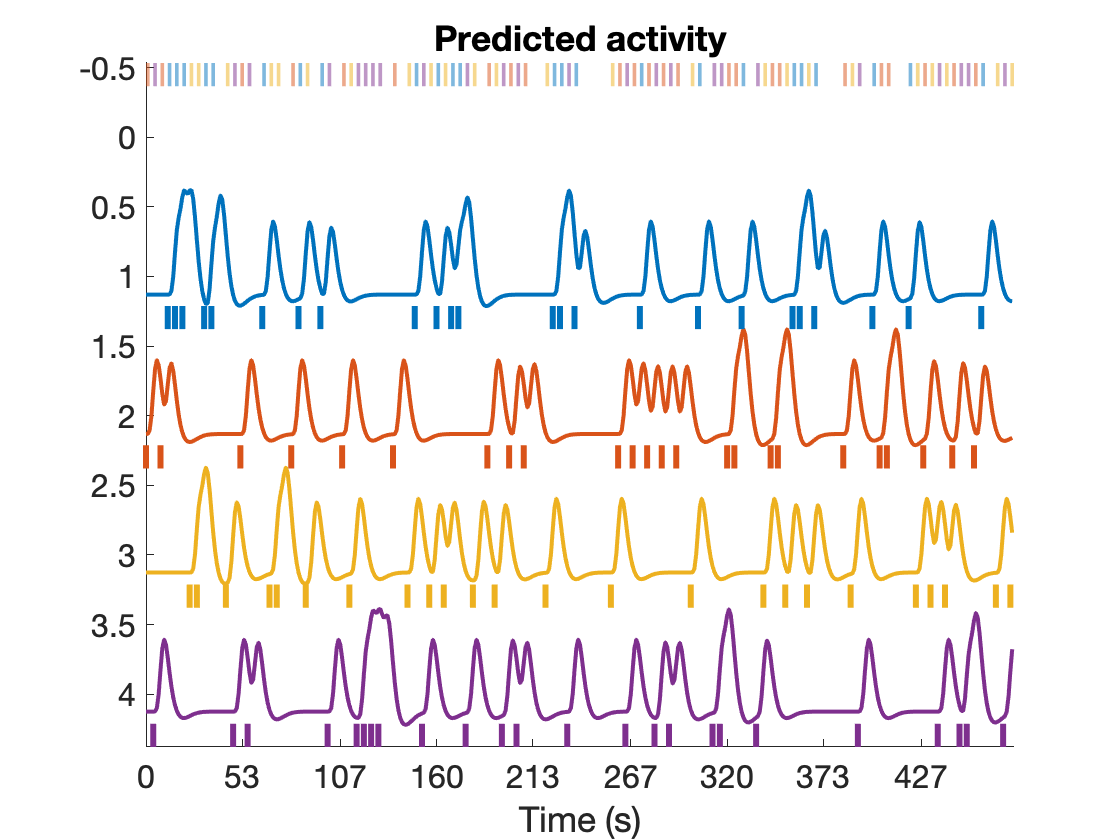

TR = 1;                 % Repetition time for scans; one image every TR; in seconds
ISI = 4;                % Inter-stimulus interval in sec (min time between events)
eventduration = 2;      % Duration of 'neural' events in sec
scanLength = 480;       % Scan length in sec
HPlength = 128;         % High-pass filter length in sec
dononlin = 0;           % Nonlinear saturation model (0 = no, 1 = yes)

freqConditions = [.2 .2 .2 .2]; % Frequencies of each condition, from 0 - 1
HPlength = 128;
dononlin = 0;

create_figure('design');
[X, e, ons] = create_random_er_design(TR, ISI, eventduration, freqConditions, HPlength, dononlin, 'scanLength', scanLength);

axis tight


e = 220.4913


disp(['e = ' num2str(e)])

**Reminder**: As before, X is the design matrix.  Which is the upright face and which is inverted are arbitrary here. Let's assign "upright" to column 1, and "inverted" to column 2. We now have another output variable, **ons**, which contains a cell array of onsets and durations (in seconds) for each event. ons{1} corresponds to Condition 1, ons{2} to Condition 2, and so forth. ons{i} can be an [n x 2] array, where the first column is onset time for each event, and the second column is the event duration in seconds. 

We can look at colinearity a few ways. The simplest one is to look at the pairwise correlations -- though this doesn't give us a complete picture.

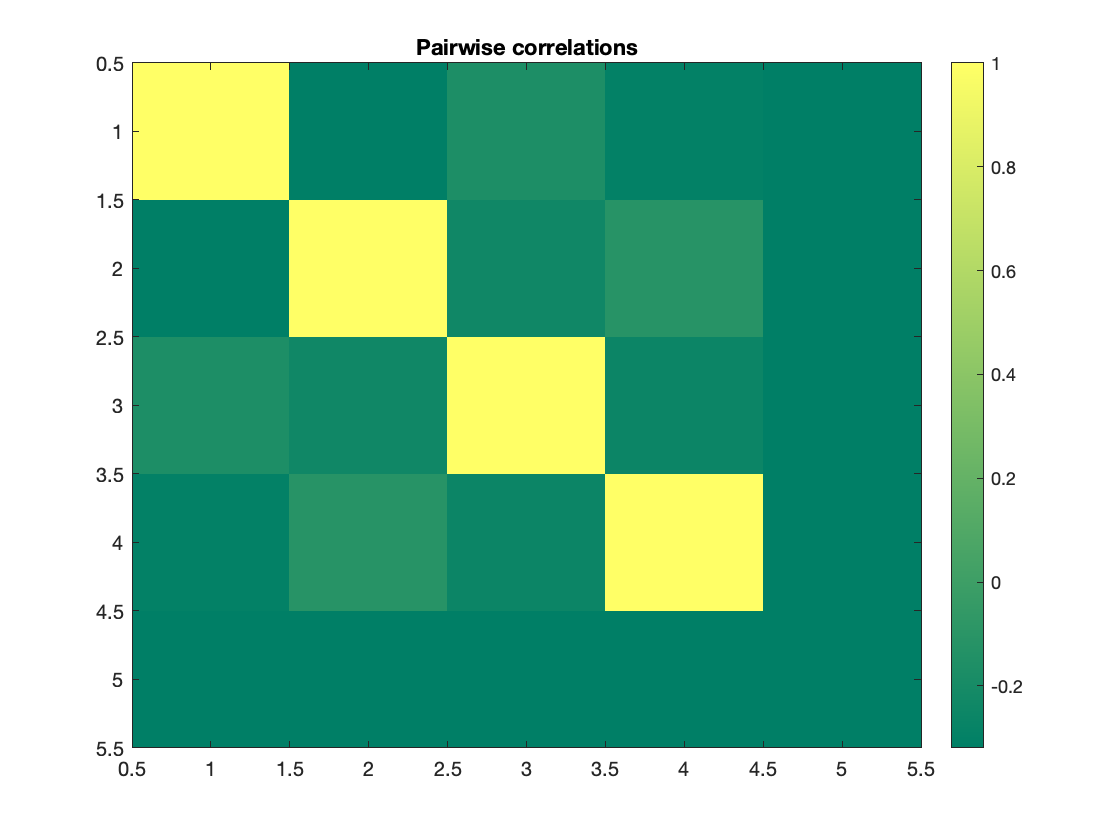

% let's plot a heat map of the correlation matrix
figure;
imagesc(corr(X))
colormap summer
axis tight; set(gca, 'YDir', 'reverse')
colorbar; 

title('Pairwise correlations')

Now, let's use the onsets to create a second design with correlated regressors. We'll use a number of the same onsets:

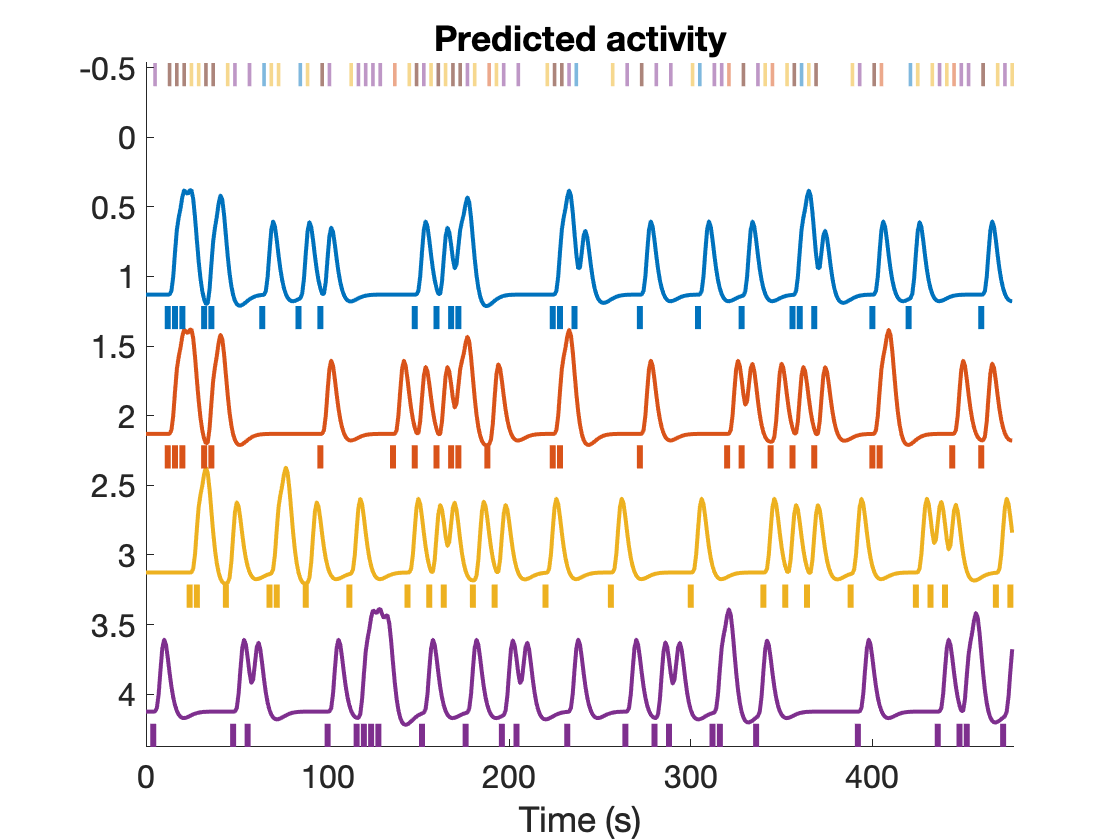

ons_new = ons;

% Replace 2/3 of condition 2's onsets with condition 1's onsets
wh = randperm(size(ons_new{2}, 1));
wh = wh(1:round(length(wh)*3/4));

ons_new{2}(wh, 1) = ons_new{1}(wh, 1);
ons_new{2}(:, 1) = sort(ons_new{2}(:, 1));

% plotDesign will generate and plot the new design matrix from the onsets

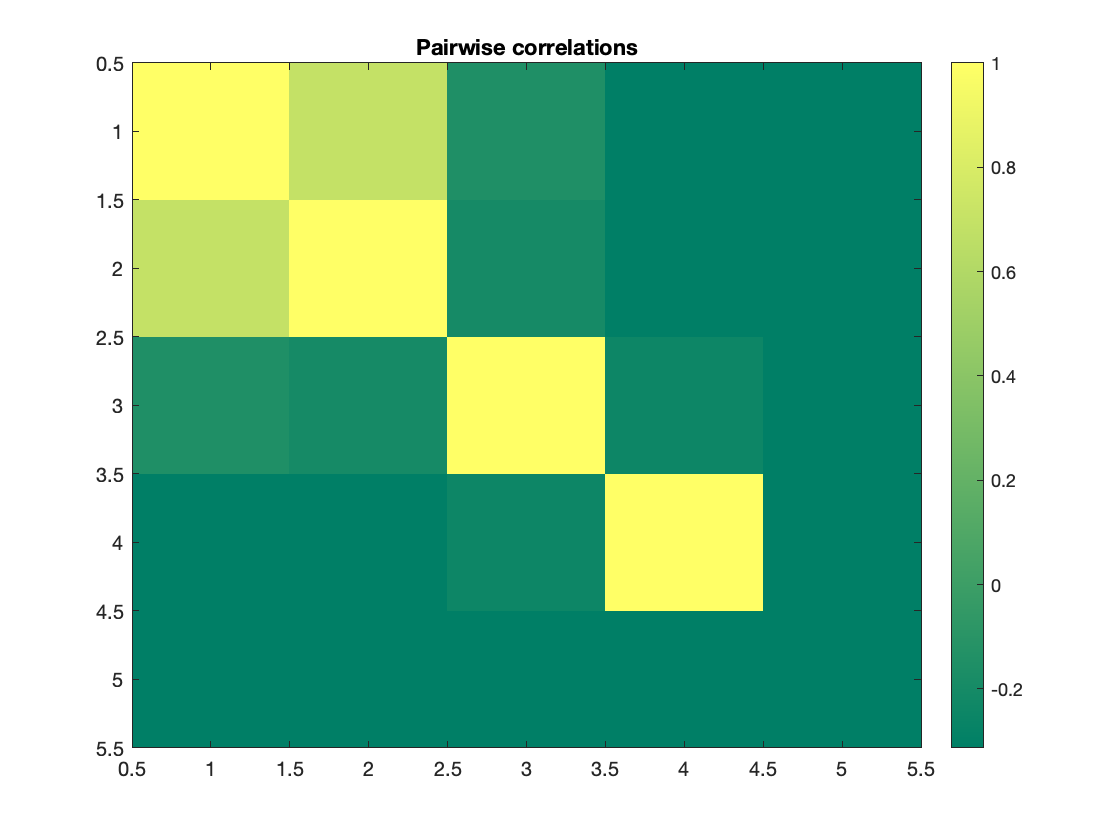

Xcoll = plotDesign(ons_new,[],TR);

% let's plot a heat map of the correlation matrix
figure;
imagesc(corr(Xcoll))
colormap summer
axis tight; set(gca, 'YDir', 'reverse')
colorbar; 

title('Pairwise correlations')


#### Questions to answer

- How strong are the correlations in the original random design? How strong are they in the correlated design?

- Which parameter estimates will be affected by the colinearity we introduced? How will they be affected?

### Variance inflation factors

Pairwise correlations will let you know if any regressor is correlated with another regressor. However, we are even more concerned about being able to explain any regressor as a linear combination of the other regressors. For example, *can one regressor be explained by any  combination of the remaining regressors?* The variance inflation factor (VIF) is a metric that can help us detect multicollinearity. Specifically, it is simply the ratio of variance in a model with multiple terms, divided by the variance of a model with only a single term. This ratio reduces to the following formula:

𝑉𝐼𝐹𝑗=11−𝑅2𝑖VIFj=11−Ri2

Where 𝑅2𝑗Rj2 is the 𝑅2R2 value obtained by regressing the 𝑗𝑡ℎjth predictor on the remaining predictors. This means that each regressor 𝑗j will have it’s own variance inflation factor.

VIFs are calculated for each regressor, based on whether it can be predicted by a combination of the others. VIFS  of 1 are "perfect" -- they indicate that the regressor is orthogonal to the other regressors. Researchers design experiments (as opposed to just measuring things in the world) because it gives them a chance to manipulate some variables independently of others, and thereby create designs where the VIFs are all 1.  

The interpretation of the VIF is the multiplicative increase in $var(\hat\beta)$for a regressor due to having other regressors in the model. There is no upper bound on VIFs, because if regressors are perfectly correlated, the increase in variance is infinite!  In practice, VIFs of 2 or more are not great, but may be OK depending on the sample size. VIFs of 4 or more are pretty bad, and 8 or more are very bad. 

If we're observing measured variables, sometimes we can't avoid multicolinearity -- though if the correlations are strong enough, we may have to concede that we can't separate their effects in our study. in these cases, researchers often simplify their design matrices by averaging over variables or picking just one variable in an intercorrelated set to include in their models. in some fields (e.g., epidemiology), experimental manipulations are difficult or impossible, and colinearity is high (sleep quality, neighborhood, income, educations, depression, exercise levels, features of diet, and early-life adversity are all intercorrelated! The strategy is to obtain very large samples along with statistical techniques to try to disentangle them, and higher VIFs may be acceptable.  Published thresholds for problematic VIFs are sometimes around 10, but this is very high!

In an fMRI experiment that you have designed, VIFs should be low! A possible exception is that you can't always control whether people's head movement and other physiology is correlated with the task regressors (we'll return to this later).

The function getvif( ) will calculate variance inflation factors for each regressor in the design matrix. The 'plot' option will additionally create a formatted plot for you.  


% Plot the variance inflation factors

Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


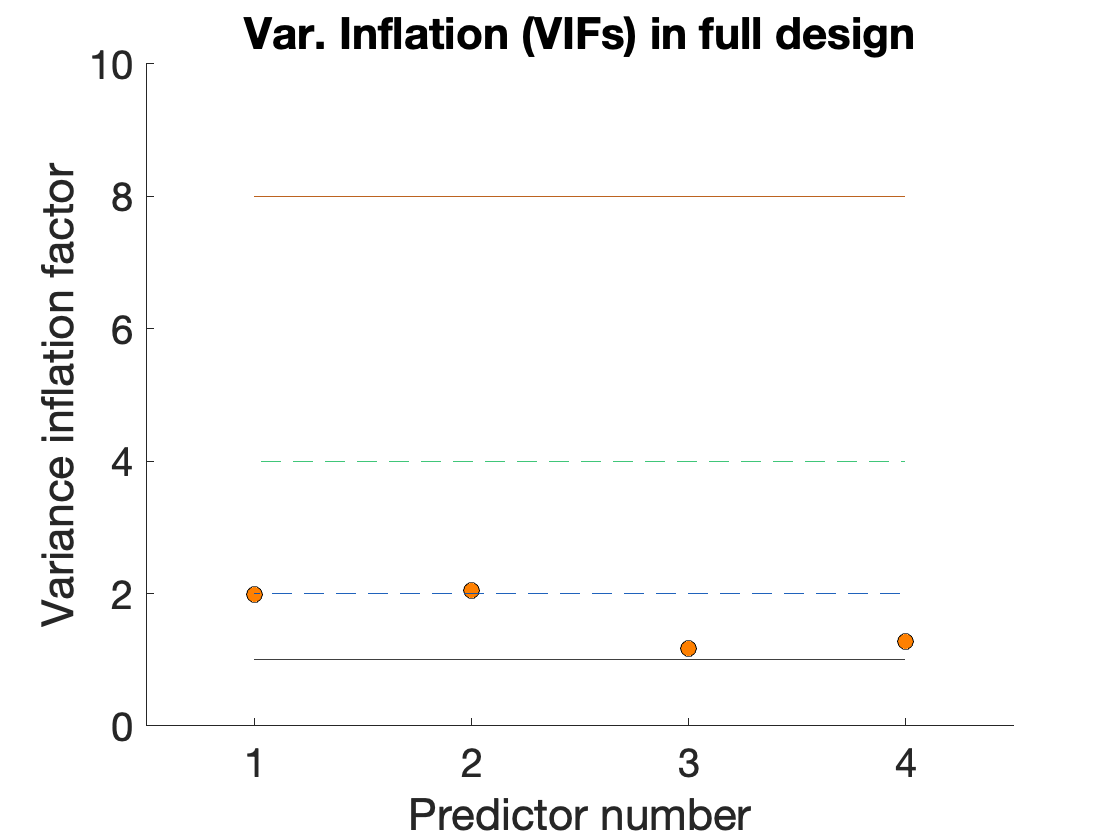

create_figure('vifs');
vifs = getvif(X, false, 'plot');


drawnow, snapnow

In the plot, variance inflation of 1 is shown by the black line, and is the minimum possible (best). Successive lines indicate doublings of variance inflation factor. Red boxes have extremely high VIFs, perfect multicolinearity. 

#### Questions to answer

- Do any regressors have high VIFs?  Are they in an acceptable range?

- Now recreate the same plot for our more colinear design matrix, Xcoll. Do any have high VIFs, and which ones? Why does this make sense?

- Why are VIFs higher for *two* regressors, not just one?

- How strong does the correlation have to be for the VIF to be around 2? (hint: corr( ) in Matlab)

An important thing to know is that pairwise correlations do not tell the whole story!  That's because a regressor may be highly correlated with no single other regressor, but with a **combination** of them. Let's create a new regressor that is a *perfect* linear combination of the first two.

X(:, 6) = .5 * X(:, 1) + .5 * X(:, 2);

#### Questions to answer

- Now recreate the plot of pairwise correlations. (You can add a code block with your code below). How do they look? Are there any "red flags" with super-high correlations? Do they look like it might be possible to estimate betas for all regressors given enough data?

- Recreate the VIF plot for the new design matrix. What do you see? Is it in fact possible to estimate betas for all regressors given enough data?

- As you increase the length of a randomized design (number of events and time scanning), what do you expect to happen to the VIFs? Can you verify this in a simulation? Hint: You can copy the code for generating a design above, creating a new code block here, but change the scanLength parameter and re-create the VIF plot.

### Colinearity and contrasts

For designs with highly colinear regressors, you can't precisely estimate the contribution of each regressor to explaining the data. However, some **contrasts** may still be estimable!

Consider this two-condition design. Let's say one condition is "faces" and the other is "houses", and I'm presenting pictures of each:

freqConditions = [.5 .5]; % Frequencies of each condition, from 0 - 1

Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


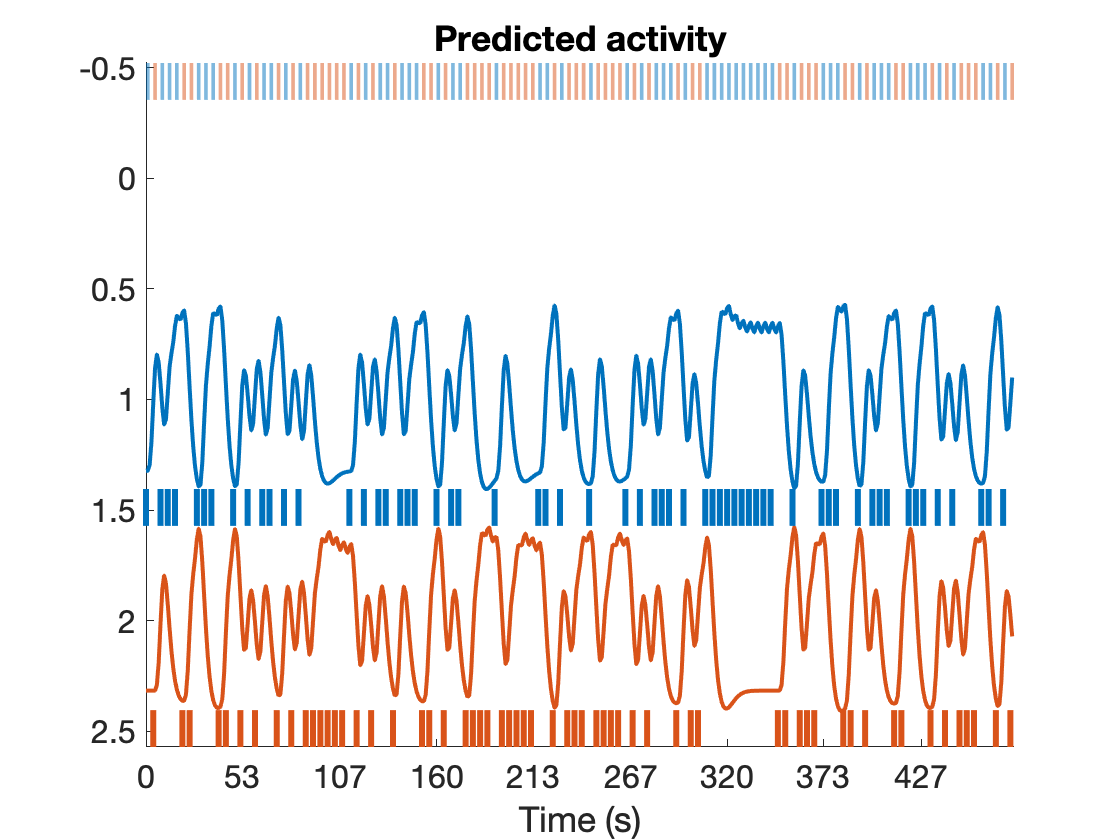

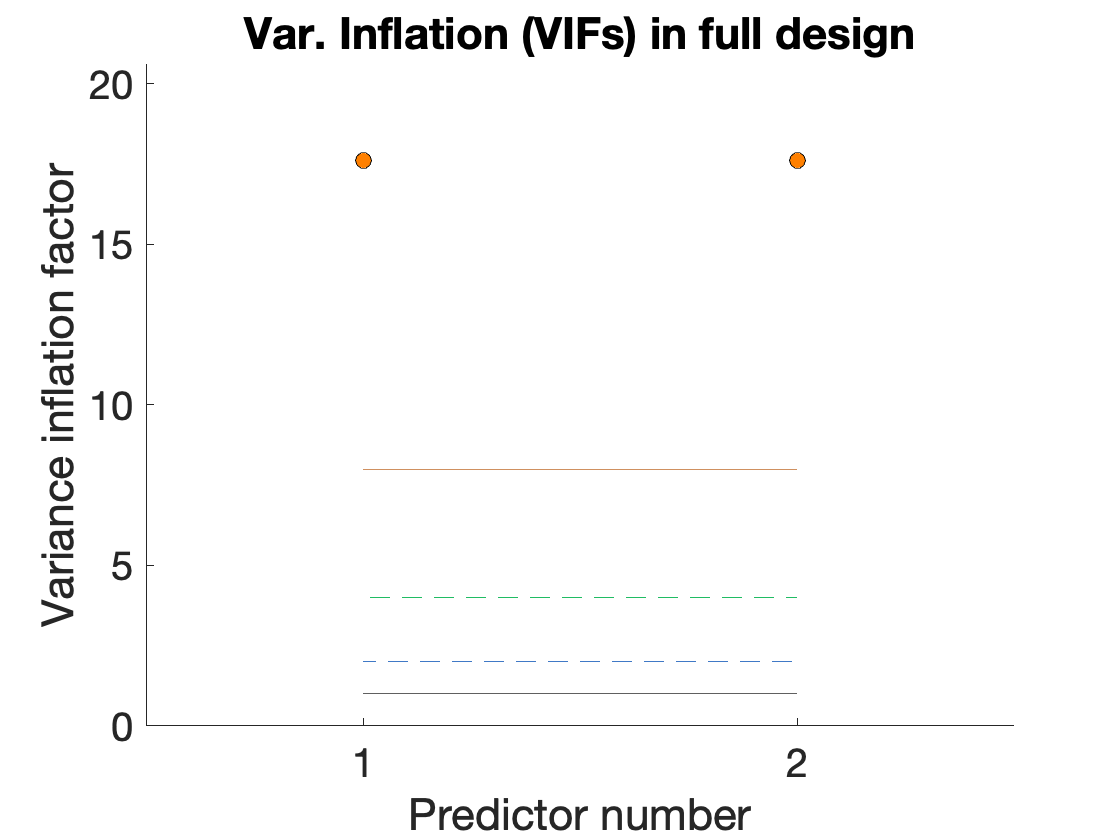


create_figure('design');

[X, e, ons] = create_random_er_design(TR, ISI, eventduration, freqConditions, HPlength, dononlin, 'scanLength', scanLength);
axis tight

create_figure('vifs');
vifs = getvif(X, false, 'plot');

drawnow, snapnow


#### Questions to answer

- What are the VIFs, approximately? Why are they so high? 

- If one regressor is "faces" and the other is "houses", what does this mean in terms of estimating neural activity increases for faces and houses?

- What could I do to reduce multicolinearity?

Now let's apply a contrast:

C = [1 -1 0]';
Xc = X*C;

This is the difference contrast for [faces - houses] 

#### Questions to answer

- Plot the contrast values (Xc) over time.  Does it look like there's variability there that might be correlated with brain activity?

- What does this mean in terms of which brain<->stimulus relationships I can estimate using this design?

The bottom line: I may not be able to  estimate how much neural activity there is for  each of "faces" and "houses" (compared to a resting baseline) separately, but I may be able to find brain areas that show a *relative* difference in activity just fine!